# Simulation Setup

wordlen = 16;
fraclen = 12;
Ftype = numerictype('DataType','Fixed',...
    'DataTypeMode','Fixed-point: binary point scaling',...
    'Signedness','Signed',...
    'WordLength',wordlen,...
    'FractionLength',fraclen);
Fmath = fimath('CastBeforeSum', true, 'OverflowAction', 'Saturate',...
    'RoundingMethod','Floor','ProductMode','SpecifyPrecision',...
    'ProductWordLength',wordlen,'ProductFractionLength',fraclen,...
    'SumMode','SpecifyPrecision','SumWordLength',wordlen,'SumFractionLength',fraclen);
one = fi(1, Ftype, Fmath);
zero = fi(0, Ftype, Fmath);

Fc = 1e6; % Carrier frequency in Hz
Fs = 6e6; % Sampling rate
Rs = 50e3; % Symbol rate in symbols/sec (baud)
B = 350e3; % Bandwidth

sps = Fs / Rs; % Number of samples per symbol

msg = 'hello world!';
msg_len_bin = arrayfun(@(x) fi(str2double(x), Ftype, Fmath), dec2bin(length(msg), 8));
msg_bin = arrayfun(@(x) fi(str2double(x), Ftype, Fmath), reshape(dec2bin(msg, 8)', 1, []));

sync_header = reshape(repmat([one zero], 4)', 1, []);

barker_code = [one one one zero zero zero one zero zero one zero];

tail = reshape(repmat([zero one], 2)', 1, []);

bits = [sync_header barker_code msg_len_bin msg_bin tail];

num_symbols = length(bits); % Number of symbols/bits to send
num_samples = num_symbols * sps; % Number of discrete samples

% Use these guys for plotting
t = linspace(0, num_symbols / Rs, num_samples); % Time variable
f = linspace(-Fs/2,Fs/2, num_samples); % Frequency variable
xview = [0.000, 0.003];

% Clear all previous figures before starting
close all;

## Mapping Bits to Symbols

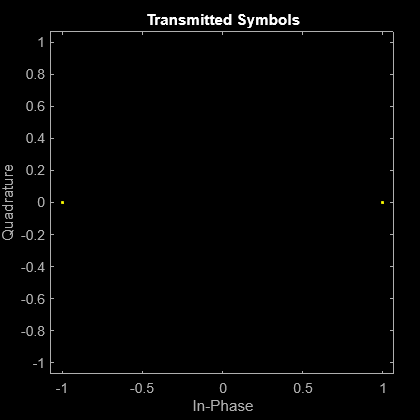

% Convert to BPSK Symbols (1's and -1's)
symbols = bits;
symbols(symbols == zero) = fi(-1, Ftype, Fmath);

% Visualize BPSK Symbols in a Constellation Diagram
scatterplot(double(symbols));
title("Transmitted Symbols");

## Upsample

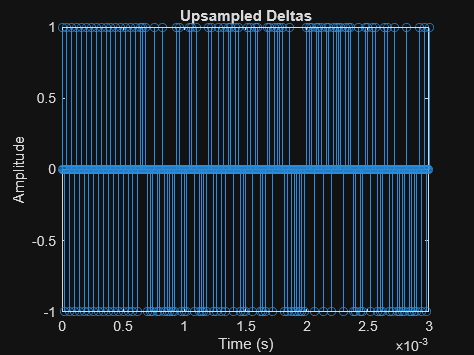

% Use upsample to form a delta train
deltas = upsample(symbols, sps);

% Visualize Deltas (xlimited to only first ~20 symbols)
figure;
stem(t, deltas);
title("Upsampled Deltas");
xlabel('Time (s)');
ylabel('Amplitude');
xlim(xview);

## Pulse Shaping

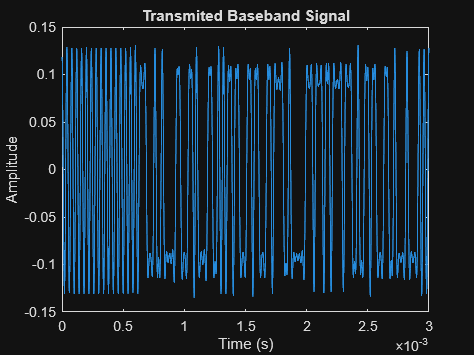

% Use an SRRC as the pulse shape filter
beta = 0.7; % RRC rolloff factor
span = 11; % number of symbols for length of filter impulse response
ps_filter = rcosdesign(beta, span, sps, 'sqrt');

% Convolve the deltas with the rectangular window
baseband_samples = conv(deltas, ps_filter, 'same');

% Visualize Transmitted Baseband Signal
figure;
plot(t, baseband_samples);
title("Transmited Baseband Signal");
xlabel('Time (s)');
ylabel('Amplitude');
xlim(xview);

## Modulate to Carrier

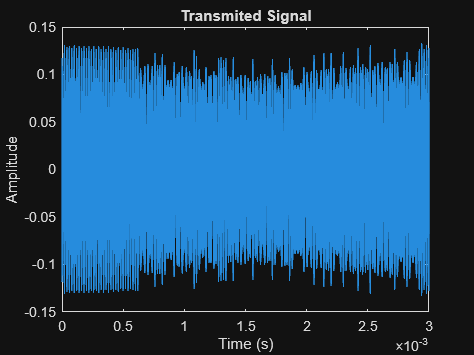

phase_offset = pi;
transmitted_signal = modulate_carrier(double(baseband_samples), Fc, t, phase_offset);

% Upsample to simulate 
sym_factor = 100;

sym_s = Fs * sym_factor;
real_sps = sym_s / Fs;
real_len = length(transmitted_signal);
real_t = linspace(0, real_len / Fs, real_len * real_sps);
real_samples = upsample(double(transmitted_signal), real_sps);
for i=1:length(real_samples)
    if real_samples(i) == 0
        real_samples(i) = real_samples(i - 1);
    end
end

% Visualize Transmitted Signal
figure;
plot(real_t, real_samples);
title("Transmited Signal");
xlabel('Time (s)');
ylabel('Amplitude');
xlim(xview);

## Transmit Over Channel

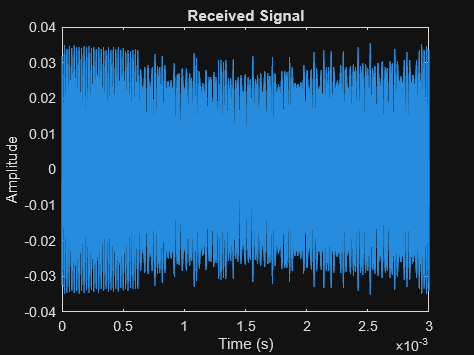

snr = 30;
fixed_gain = 2;
received_signal = add_channel_impairments(real_samples, B, Fc, Fs, snr);

figure;
plot(real_t, received_signal);
title("Received Signal");
xlabel('Time (s)');
ylabel('Amplitude');
xlim(xview);

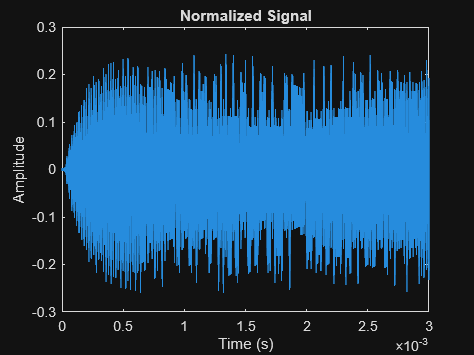


rx_Fs = 3e6;
sampled_signal = fi(downsample(received_signal, (Fs * sym_factor) / rx_Fs), Ftype, Fmath);

rx_sps = rx_Fs / Rs;
t_sample = linspace(0, num_symbols / Rs, num_symbols * rx_sps); % Time variable
% Normalize the signal for stability of PID tuning constants
AGC_kp = 1.8;
AGC_ki = 0;
AGC_kd = 0.1;
ref = fi(0.1, Ftype, Fmath);
M = 60;
[normalized_signal, gain, err] = AGC(sampled_signal, AGC_kp, AGC_ki, AGC_kd, ref, M);

figure;
plot(t_sample, normalized_signal)
title("Normalized Signal")
xlabel('Time (s)');
ylabel('Amplitude');
xlim(xview);

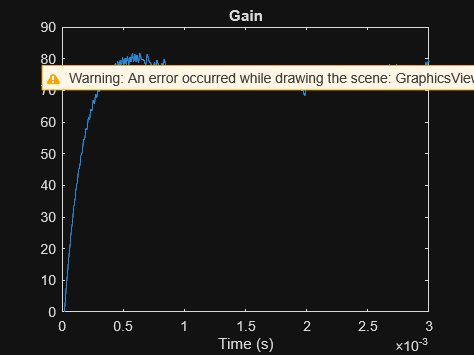



% Plot the Gain
figure;
plot(t_sample, gain)
title("Gain")
xlabel('Time (s)');
xlim(xview);

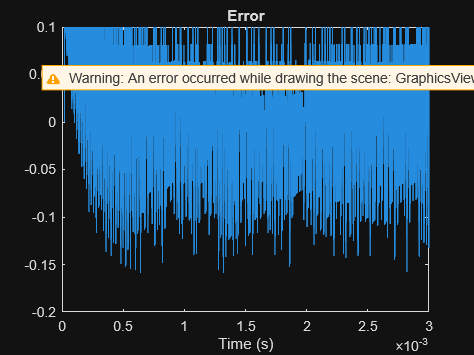


% Plot the Error
figure;
plot(t_sample, err)
title("Error")
xlabel('Time (s)');
xlim(xview);

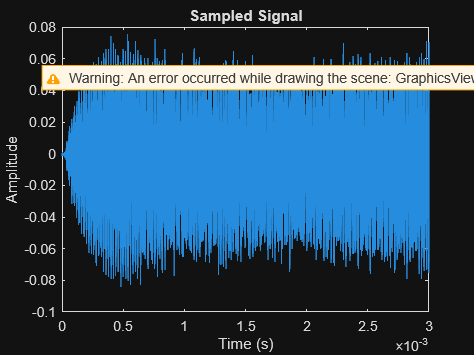



lowpass = designfilt('lowpassfir', 'FilterOrder', 7, 'CutoffFrequency', 1e6, 'SampleRate', Fs).Coefficients;
filtered_signal = conv(upsample(normalized_signal, Fs / rx_Fs), lowpass, 'same');

% Plot the Received Signal
figure;
plot(t, filtered_signal)
title("Sampled Signal")
xlabel('Time (s)');
ylabel('Amplitude');
xlim(xview);

## Demodulation

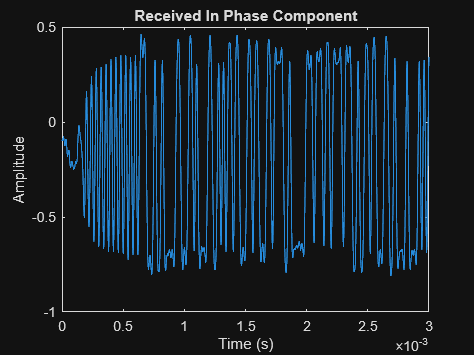

% Encorporate a frequency offset
carrier_frq = Fc + (Fc * 0.03);

% PID Tuning Constants
%Kp = 32;
%Ki = 2;
%Kd = 8;
Kp = 8;
Ki = 0.25;
Kd = 0.1;
% Costas Loop to extract I and Q components
[I, Q, theta, err] = costas_loop(filtered_signal, carrier_frq, Fs, t, Kp, Ki, Kd, Ftype, Fmath);

I_ps = conv(I, ps_filter, 'same');

figure;
plot(t, I_ps)
title("Received In Phase Component")
xlabel('Time (s)');
ylabel('Amplitude');
xlim(xview);

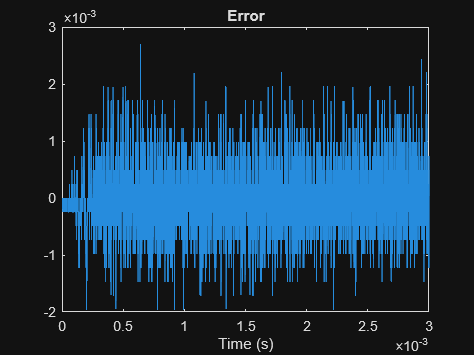


% Plot the Error
figure;
plot(t, err)
title("Error")
xlabel('Time (s)');
xlim(xview);

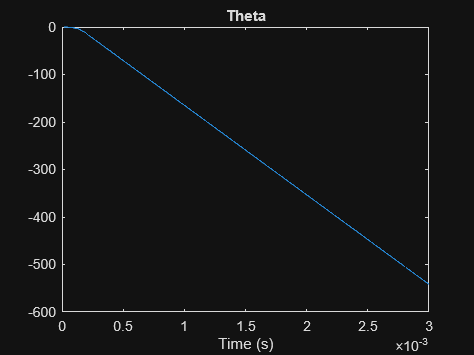


% Plot the Theta
figure;
plot(t, theta(1:length(t)))
title("Theta")
xlabel('Time (s)');
xlim(xview);

## Sample and Detect Symbols

% TODO 1.1: Apply SPS frequency offset at the receiver
sps_offset = sps - 1;

% TODO 1.2: Apply SPS phase offset at the receiver
shift_samples = circshift(I_ps, sps*0.5)

shift_samples =   Columns 1 through 3276
    0.2361    0.2283    0.2241    0.2168    0.2097    0.2029    0.1956    0.1882    0.1824    0.1758    0.1719    0.1646    0.1592    0.1516    0.1450    0.1396    0.1328    0.1272    0.1223    0.1160    0.1099    0.1038    0.0989    0.0930    0.0886    0.0837    0.0776    0.0720    0.0676    0.0613    0.0564    0.0518    0.0464    0.0410    0.0376    0.0327    0.0288    0.0210    0.0171    0.0125    0.0078    0.0034   -0.0007   -0.0068   -0.0110   -0.0159   -0.0203   -0.0237   -0.0264   -0.0310   -0.0361   -0.0381   -0.0422   -0.0444   -0.0481   -0.0510   -0.0532   -0.0576   -0.0601   -0.0632   -0.0928   -0.0935   -0.0940   -0.0947   -0.0955   -0.0962   -0.0969   -0.0969   -0.0964   -0.0967   -0.0967   -0.0972   -0.0972   -0.0972   -0.0967   -0.0972   -0.0974   -0.0977   -0.0977   -0.0977   -0.0977   -0.0977   -0.0977   -0.0977   -0.0979   -0.0979   -0.0979   -0.0981   -0.0984   -0.0984   -0.0984   -0.0979   -0.0972   -0.0964   -0.0959   -0.095

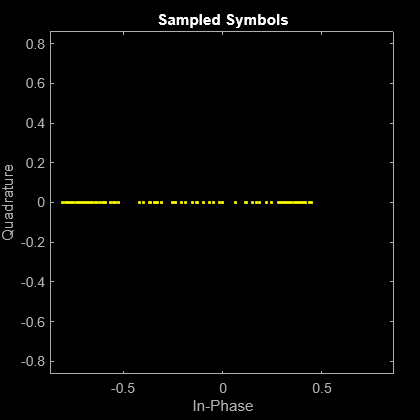


% Naively sample the received signal at the symbol rate to get the received symbols
naive_received_symbols = downsample(shift_samples, sps_offset);

% Visualize the received symbols in a constellation diagram (scatterplot)
scatterplot(double(naive_received_symbols(33:end-11)));
title("Sampled Symbols");


% Normalize for stability for PID stability
% sigma_sqr = 1
% TODO Section 2: Implement one (or multiple) of the timing error detectors to properly sample
% PID Tuning Constants
Kp = 2 % observe how Kp causes faster settling w/o oscillation but increases self-noise effect

Kp = 2

Ki = 0.1 % observe how Ki smooths the oscillations before settling to a constant offset (but eventually goes unstable)

Ki = 0.1000

Kd = 0 % observe how Kd increases high frequency noise in the lock

Kd = 0


% Recreate the downsample function iteratively, then implement the TED

[symbs, phase_offsets] = my_downsample(shift_samples, sps_offset, Kp, Ki, Kd);

% TODO: Visualize the properly receieved samples
% Note: A good chunk of the early symbols might be garbage as the TED locks on, so feel free
%       to only plot the later end of the symbols

mdl = fitlm((length(phase_offsets)-50:length(phase_offsets)),phase_offsets(end-50:end))

mdl = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate         SE        tStat       pValue  
                   _________    __________    ______    __________

    (Intercept)     -0.50751      0.016225    -31.28    4.8617e-34
    x1             0.0085795    0.00012216    70.233    7.5995e-51


Number of observations: 51, Error degrees of freedom: 49
Root Mean Squared Error: 0.0128
R-squared: 0.99,  Adjusted R-Squared: 0.99
F-statistic vs. constant model: 4.93e+03, p-value = 7.6e-51

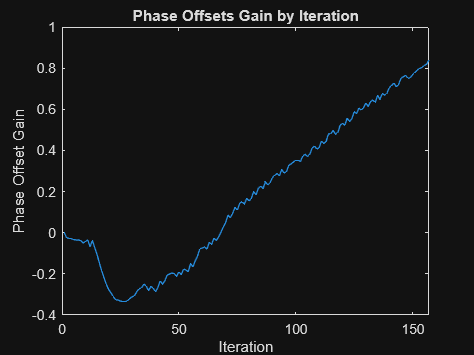


figure;
plot(1:length(phase_offsets), phase_offsets);
title("Phase Offsets Gain by Iteration")
xlabel('Iteration');
ylabel('Phase Offset Gain');

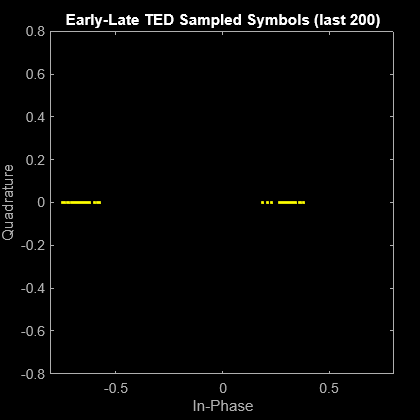


scatterplot(symbs(33:end-11));
title("Early-Late TED Sampled Symbols (last 200)")


% TODO: You'll probably want to change this once you have the timing error detector
received_symbols = symbs;

% Apply Thresholding to detect the symbols (turning them back to 1's and -1's)
received_symbols(received_symbols > 0) = 1;
received_symbols(received_symbols <= 0) = 0;

## Detect Message

bcode_len = length(barker_code);
msg_start = 0;
for i=1:(length(received_symbols)-bcode_len)
    if all(~xor(barker_code, received_symbols(i:i+bcode_len-1)))
        msg_start = i+bcode_len;
        break;
    elseif all(xor(barker_code, received_symbols(i:i+bcode_len-1)))
        received_symbols = ~received_symbols;
        msg_start = i+bcode_len;
        break;
    end
end
msg_len = bin2dec(num2str(received_symbols(msg_start:msg_start+7), '%1d'));
rx_bits = received_symbols(msg_start+8:msg_start+7+(8*msg_len));
rx_msg = char(bin2dec(reshape(num2str(rx_bits, '%1d'), 8, []).')).'

rx_msg = 'hello world!'